# Lesson III.1: The Gram-Schmidt Orthonormalization Process and the QR Factorization

In its simplest form, the Gram-Schmidt orthonormalization process is an algorithm taking a basis $\{{\bf u}_1,~{\bf u}_2,\dots,{\bf u}_n\}$ for a subspace $U\subset{\mathbb R}^n$ and producing an orthonormal basis $\{{\bf w}_1,~{\bf w}_2,\dots,{\bf w}_n\}$for $U$, i.e.,  

        (III.1.1)        $\text{Span}\{{\bf u}_1,\dots,{\bf u}_\ell\}~=~
\text{Span}\{{\bf w}_1,\dots,{\bf w}_\ell\}=U \qquad\text{for}~\ell=1,2,\dots,n.$

The $n\times n$ matrix having the basis vectors$\{{\bf u}_1,~{\bf u}_2,\dots,{\bf u}_n\}$as its columns are then factored as

        (III.1.2)        $\left[\matrix{{\bf u}_1&{\bf u}_2&\cdots& {\bf u}_n}\right]~=~QR$ 

where the $n\times n$ matrix $Q=\left[\matrix{{\bf w}_1 & {\bf w}_2 & \cdots & {\bf w}_n}\right]$is orthogonal and the $n\times n$ matrix $R$ is upper triangular.   The Gram-Schmidt algorithm and its algebraic expression as the QR factorization power are widely used techniques for optimization.

**The Gram-Schmidt orthonormalization process.   **Given a basis $\{{\bf u}_1,~{\bf u}_2,\dots,{\bf u}_n\}$ for ${\mathbb R}^n$, we define the subspaces

        (III.1.3)        $U_\ell=\text{Span}\{{\bf u}_1,\dots,{\bf u}_\ell\}$    for    $\ell=1,\dots,n$.

These subspaces are nested

        (III.1.4a)        $U_\ell\subset U_{\ell+1}$

and

        (III.1.4b)        $\text{dim}(U_\ell)~=~\ell$.

The strategy of the Gram-Schmidt algorithm is to first generate an orthogonal basis $\{{\bf v}_1,~{\bf v}_2,\dots,{\bf v}_n\}$such that $U_\ell=\text{Span}\{{\bf v}_1,\dots,{\bf v}_\ell\}$ for $\ell=1,\dots,n$.   To start, we take 

        (III.1.5)        ${\bf v}_1={\bf u}_1$.

If we were to add ${\bf u}_2$ to this basis, then the set $\{{\bf v_1},~{\bf u}_2\}$would indeed span $U_2$, but there is no guarantee that these two vectors would be orthogonal.    To remedy this concern, we instead choose ${\bf v}_2$ to be the orthogonal projection of ${\bf u}_2$ into the orthogonal complement of $U_1$.   This assures that $\{{\bf v}_1,{\bf v}_2\}$ is orthogonal. 

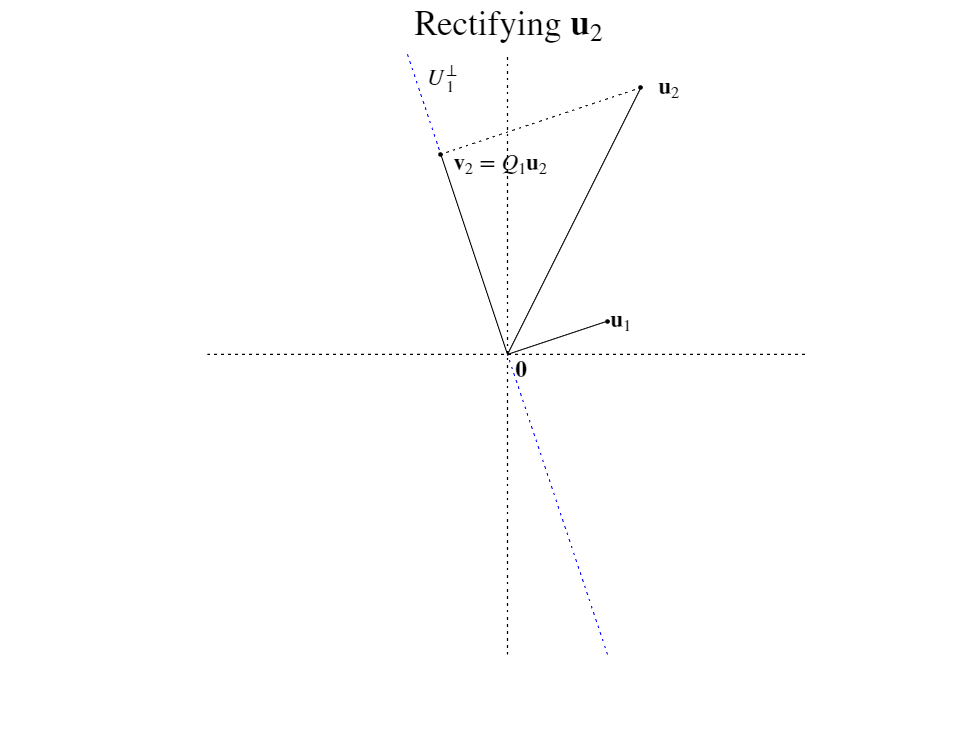

figII9a()

More generally, we apply this strategy each time we add a new vector to the orthogonal basis$\{{\bf v}_1,~{\bf v}_2,\dots,{\bf v}_\ell\}$ for $U_\ell$ to obtain an orthogonal basis for $U_{\ell+1}$.   Specifically, we take

        (III.1.6)        ${\bf v}_{\ell+1}=Q_\ell {\bf u}_{\ell+1}$        where    $Q_\ell$    is orthogonal projection into $U_\ell^\perp$.

Now $Q_\ell=I-P_\ell$ where $P_\ell$ is orthogonal projection into $U_\ell$.   We compute $P_\ell$ in terms of the orthogonal basis$\{{\bf v}_1,~{\bf v}_2,\dots,{\bf v}_\ell\}$:

        (III.1.7)        $P_\ell=\left[\matrix{{\bf v}_1&\cdots&{\bf v}_\ell}\right]\big(
\left[\matrix{{\bf v}_1&\cdots&{\bf v}_\ell}\right]^T\left[\matrix{{\bf v}_1&\cdots&{\bf v}_\ell}\right]\big)^{-1} \left[\matrix{{\bf v}_1&\cdots&{\bf v}_\ell}\right]^T$.

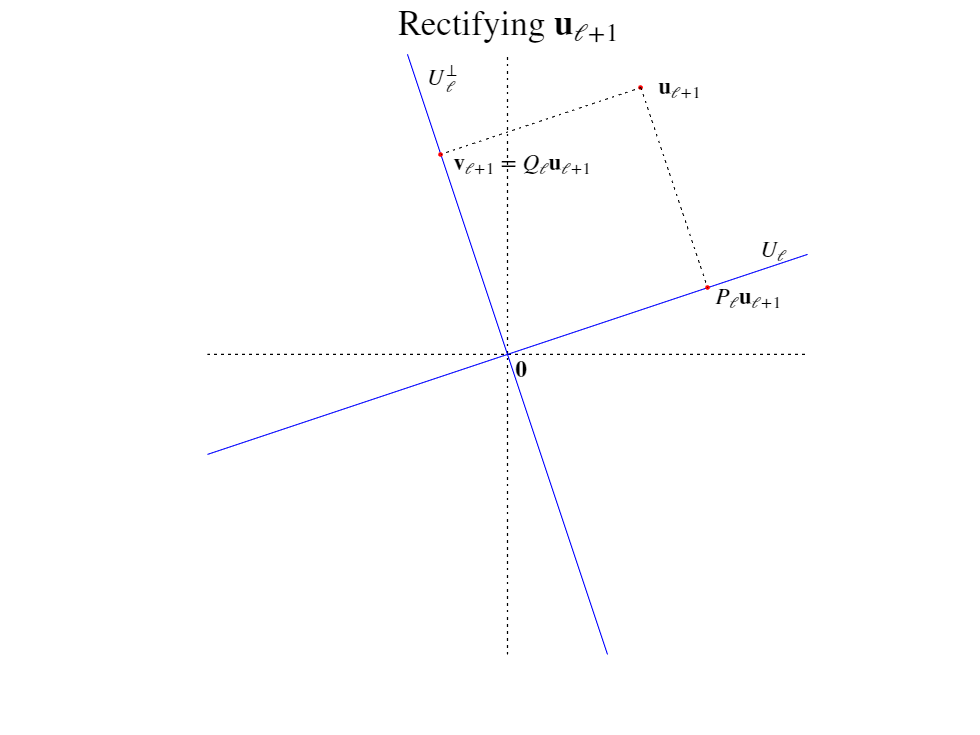

figII9b()

Because$\left[\matrix{{\bf v}_1&\cdots&{\bf v}_\ell}\right]$ has orthogonal columns, its Gram matrix is diagonal:


$$\big(\left[\matrix{{\bf v}_1&\cdots&{\bf v}_\ell}\right]^T\left[\matrix{{\bf v}_1&\cdots&{\bf v}_\ell}\right]\big)^{-1}~
=~\left[\matrix{ 
{\bf v}_1\cdot{\bf v}_1 &  & & \cr
& {\bf v}_2\cdot{\bf v}_2 & &\cr
&&\ddots &\cr
& &&{\bf v}_\ell\cdot{\bf v}_\ell
}\right]^{-1}~
=~\left[\matrix{
||{\bf v}_1||^{-2} &  &  &  \cr
& ||{\bf v}_2||^{-2}& & \cr
 &&\ddots& \cr
&& & ||{\bf v}_\ell||^{-2}\cr
}\right]$$


Hence, expanding $P_\ell$ in outer products gives

        (III.1.8)        $P_\ell = \sum_{j=1}^\ell \frac1{||{\bf v}_j||^2}{\bf v}_j{\bf v}_j^T$.

Hence,

        (III.1.9)        ${\bf v}_{\ell+1} = (I-P_\ell){\bf u}_{\ell+1}$$~=~{\bf u}_{\ell+1}~-~\sum_{j=1}^\ell \left(\frac{{\bf v}_j\cdot{\bf u}_{\ell+1}}{{\bf v}_j\cdot{\bf v}_j}\right) {\bf v}_j$.

As an example, consider $\left[\matrix{{\bf u}_1 &{\bf u}_2 &{\bf u}_3}\right]=\left[\matrix{1 & 1 & 1 \cr 1 & 2 & 0 \cr 1 & 1 & -1}\right]$.


$$\matrix{{\bf v}_1 &=& {\bf u}_1 \qquad\qquad\qquad\qquad\quad&=& \left[\matrix{1\cr1\cr1}\right]\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad\quad&=&\left[\matrix{1\cr1\cr1}\right]\cr
{\bf v}_2&=&{\bf u}_2~-~\frac{{\bf v}_1\cdot{\bf u}_2}{{\bf v}_1\cdot{\bf v}_1}{\bf v}_1\quad\qquad\quad&=&\left[\matrix{1\cr2\cr1}\right]~-~\frac{1+2+1}{1+1+1}\left[\matrix{1\cr1\cr1}\right]\qquad\qquad\qquad\qquad\qquad&=&\frac13\left[\matrix{-1\cr2\cr-1}\right]\cr
{\bf v}_3&=&{\bf u}_3-\frac{{\bf v}_1\cdot{\bf u}_3}{{\bf v}_1\cdot{\bf v}_1}{\bf v}_1-
\frac{ {\bf v}_2\cdot{\bf u}_3 }{ {\bf v}_2\cdot{\bf v}_2}{\bf v}_2&=&\left[\matrix{1\cr0\cr-1}\right]~-~
\frac{1+0-1}{1+1+1}\left[\matrix{1\cr1\cr1}\right]~-~\frac{-\frac13+0+\frac13}{\frac19+\frac49+\frac19}\left[\matrix{-1/3\cr2/3\cr-1/3}\right]&=&\left[\matrix{1\cr0\cr-1}\right]
}$$


Once the orthogonal basis $\{{\bf v}_1,\dots,{\bf v}_n\}$is found, the orthonormal basis $\{{\bf w}_1,\dots,{\bf w}_n\}$ is found by normalization:

        (III.1.10)        ${\bf w}_j~=~\frac{1}{||{\bf v}_j||} {\bf v}_j$    for     $j=1,\dots,n$.

For the example above

        ${\bf w}_1=\frac1{\sqrt{3}}\left[\matrix{1\cr1\cr1}\right],\qquad{\bf w}_2=\frac1{\sqrt{6}}\left[\matrix{-1\cr2\cr-1}\right],\qquad
{\bf w}_3=\frac1{\sqrt{2}}\left[\matrix{1\cr0\cr-1}\right]$.

In summary, the Gram-Schmidt algorithm consists of the repeated application of (III.1.9) to produce an orthogonal basis which is then normalized using (III.1.10) 

**QR Factorization.**    The orthonormal basis$\{{\bf w}_1,\dots,{\bf w}_n\}$produced by the Gram-Schmidt process is naturally arranged as the columns of an orthogonal matrix:

        (III.1.11)        $Q~=~\left[\matrix{{\bf w}_1&\cdots&{\bf w}_n}\right]$.

This allows the matrix having the original basis as its columns, $A=\left[\matrix{{\bf u}_1&\cdots&{\bf u}_n}\right]$, to be factored as 

        (III.1.12)        $A~=~Q R$

where $Q$ is orthogonal and $R$ is upper triangular.   The reason that $R$ is upper triangular is that ${\bf u}_\ell\in U_\ell=\text{Span}\{{\bf w}_1,\cdots,{\bf w}_\ell\}$, that is, ${\bf u}_\ell$ is a linear combination of the first $\ell$ columns of $Q$.  Because $Q$ is orthogonal, 

        (III.1.13)        $R~=~Q^TA$.

In the example above,


$$A~=~\left[\matrix{1&1&1\cr1&2&0\cr1&1&-1}\right]\qquad\text{and}\qquad
Q~=~\left[\matrix{
\frac{1}{\sqrt{3}} & -\frac{1}{\sqrt{6}} & \frac{1}{\sqrt{2}} \cr
\frac{1}{\sqrt{3}} & \frac{2}{\sqrt{6}}& 0 \cr
\frac{1}{\sqrt{3} & -\frac{1}{\sqrt{6}} & -\frac{1}{\sqrt{2}}}\right]$$


Hence,

$R=Q^TA=\left[\matrix{
\frac1{\sqrt{3}} & \frac1{\sqrt{3}} & \frac1{\sqrt{3}} \cr
-\frac1{\sqrt{6}} & \frac2{\sqrt{6}} & -\frac1{\sqrt{6}} \cr
\frac1{\sqrt{2}} & 0 & -\frac1{\sqrt{2}}
}\right]
\left[\matrix{1&1&1\cr 1&2&0\cr 1&1&-1}\right]~=~
\left[\matrix{
\frac3{\sqrt{3}} & \frac4{\sqrt{3}} & 0 \cr
0 & \frac2{\sqrt{6}} & 0 \cr
0 & 0 & \frac2{\sqrt{2}}}\right]=\left[\matrix{\sqrt{3} & \frac{4\sqrt{3}}3 & 0 \cr 0 & \frac{\sqrt{6}}3 & 0 \cr 0 & 0 & \sqrt{2}}\right]$.

In doing computation, checking that $R$ is indeed upper triangular is a sensible check.   Reporting $R$ as a matrix that is not upper triangular is not sensible unless you are just short of time.

**Extension to dependent sets of vectors.**   In the earlier description of the Gram-Schmidt process, it was assumed that $A=\left[\matrix{{\bf u}_1&\cdots&{\bf u}_n}\right]
$ is a square matrix with linearly independent columns.   If the columns are dependent, then we will at some point encounter a vector ${\bf u}_{p+1}$ that is a linear combination of the columns before it.  In that case,

                
$${\bf 0}=Q_p {\bf u}_{p+1}$$


which is of course unsuitable as an element of a basis.  In this case, we simply ignore the dependent column and continue with the next column.

Consider as an example:  $A=\left[\matrix{3&0&6&1\cr 4&0&8&1\cr 0&3&3&0\cr0&4&4&0}\right].$


$${\bf v_1}=\left[\matrix{3\cr4\cr0\cr0}\right]$$



$${\bf v}_2=\left[\matrix{0\cr0\cr3\cr4}\right]-\frac{0+0+0+0}{0+0+9+16}\left[\matrix{3\cr4\cr0\cr0}\right]=\left[\matrix{0\cr0\cr3\cr4}\right]$$


So far so good, but the third column proves problematic:


$${\bf v}_3=\left[\matrix{6\cr8\cr3\cr4}\right]-\frac{18+32+0+0}{9+16+0+0}\left[\matrix{3\cr4\cr0\cr0}\right]-\frac{0+0+9+16}{0+0+9+16}\left[\matrix{0\cr0\cr3\cr4}\right]=\left[\matrix{0\cr0\cr0\cr0}\right]$$


Obviously, we cannot use ${\bf 0}$ as a basis vector.   So we ignore the third column and try again with the fourth column:


$${\bf v}_3=\left[\matrix{1\cr1\cr0\cr0}\right]-\frac{3+4+0+0}{9+16+0+0}\left[\matrix{3\cr4\cr0\cr0}\right]-\frac{0+0+0+0}{0+0+9+16}\left[\matrix{0\cr0\cr3\cr4}\right]=\left[\matrix{4/25\cr-3/25\cr0\cr0}\right]$$


Normalizing, we obtain an orthonormal basis for $\text{col}(A)$ but not all of ${\mathbb R}^4$.

        
$$\quad{\bf w}_1=\frac15\left[\matrix{3\cr4\cr0\cr0}\right]\qquad{\bf w}_2=\frac15\left[\matrix{0\cr0\cr3\cr4}\right]\qquad
{\bf w}_3=\frac15\left[\matrix{4\cr-3\cr0\cr0}\right]$$


The matrix $Q=\left[\matrix{{\bf w}_1 &{\bf w}_2&{\bf w}_3}\right]$has orthonormal columns; hence, $Q^TQ=I$.   Of course, $Q$ is not orthogonal as it is not square.

Q=(1/5)*[3 0 4; 4 0 -3; 0 3 0; 0 4 0];
Q'*Q

ans =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000


Q*Q'

ans =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    0.3600    0.4800
         0         0    0.4800    0.6400


Nonetheless, this allows factoring $A$ as $QR$ where $R=Q^TA$.

A=[3 0 6 1; 4 0 8 1; 0 3 3 0 ; 0 4 4 0];
R=Q'*A

R =     5.0000         0   10.0000    1.4000
         0    5.0000    5.0000         0
         0         0         0    0.2000


$R$ is upper trapezoidal or more precisely proto-row-echelon.  Hence, any $m\times n$ matrix $A$ may be factored as $QR$ where $Q$ is an $m\times r$ matrix with orthonormal columns forming a basis for $\text{col}(A)$ and $R$ is an $r\times n$ proto-row-echelon matrix.   

**Extension of a basis for a subspace to **${\mathbb R}^n$.   In the previous example, the basis obtained was for the three-dimensional subspace $\text{col}(A)$.   If it is desirable to complete the basis so that $Q$ is square and hence orthogonal, this can be accomplished by augmenting the original matrix with the identity matrix and continuing the Gram-Schmidt process.

Continuing the previous example in this manner:

${\bf v}_4=\left[\matrix{1\cr0\cr0\cr0}\right]-\frac{3}{25}\left[\matrix{3\cr4\cr0\cr0}\right]-\frac{0}{25}\left[\matrix{0\cr0\cr3\cr4}\right]-\frac{4/25}{1/25}\left[\matrix{4/25\cr-3/25\cr0\cr0}\right]=\left[\matrix{0\cr0\cr0\cr0}\right]$.

Unfortunately, ${\bf e}_1\in U_3$, so we ignore this column and proceed to the next:

${\bf v}_4=\left[\matrix{0\cr1\cr0\cr0}\right]-\frac{4}{25}\left[\matrix{3\cr4\cr0\cr0}\right]-\frac{0}{25}\left[\matrix{0\cr0\cr3\cr4}\right]+\frac{3/25}{1/25}\left[\matrix{4/25\cr-3/25\cr0\cr0}\right]=\left[\matrix{0\cr0\cr0\cr0}\right]$.

Again we find ${\bf e}_2\in U_3$, so we ignore this column and proceed to the next:

${\bf v}_4=\left[\matrix{0\cr0\cr1\cr0}\right]-\frac{0}{25}\left[\matrix{3\cr4\cr0\cr0}\right]-\frac{3}{25}\left[\matrix{0\cr0\cr3\cr4}\right]+\frac{0}{1/25}\left[\matrix{4/25\cr-3/25\cr0\cr0}\right]=\left[\matrix{0\cr0\cr16/25\cr-12/25}\right]$.

Normalizing gives


$${\bf w}_4=\frac{1}{5}\left[\matrix{0\cr0\cr4\cr-3}\right]$$


And $Q$ can be completed:  $Q=\frac15\left[\matrix{3&0&4&0\cr4&0&-3&0\cr0&3&0&4\cr0&4&0&-3}\right]$.

Q=[3 0 4 0; 4 0 -3 0; 0 3 0 4; 0 4 0 -3]/5

Q =     0.6000         0    0.8000         0
    0.8000         0   -0.6000         0
         0    0.6000         0    0.8000
         0    0.8000         0   -0.6000


Q'*Q

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Q*Q'

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R=Q'*A

R =     5.0000         0   10.0000    1.4000
         0    5.0000    5.0000         0
    0.0000         0    0.0000    0.2000
         0    0.0000    0.0000         0


Q*R

ans =     3.0000         0    6.0000    1.0000
    4.0000         0    8.0000    1.0000
         0    3.0000    3.0000         0
         0    4.0000    4.0000         0


Extending the orthonormal basis for $\text{col}(A)$ to an orthonormal basis for ${\mathbb R}^m$ allows the factorization of $A$ as $QR$ where 

- $Q$ is an $m\times m$ orthogonal matrix where the first $r=\text{rank}(A)$ columns form a basis for $\text{col}(A)$ and the last $m-r$ columns form a basis for $\text{nul}(A^T)=\text{col}(A)^\perp$ and

- $R$ is a proto-row-echelon matrix ($R\sim\text{rref}(A)).$

This version of the QR factorization is the default version produced by MATLAB.

A=[1 2 3; 4 5 6; 7 8 9];      % our favorite rank deficient matrix
[Q, R]=qr(sym(A))

$$Q = \left(\begin{array}{ccc} \frac{\sqrt{66}}{66} & \frac{3\,\sqrt{11}}{11} & \frac{\sqrt{6}}{6}\\ \frac{2\,\sqrt{66}}{33} & \frac{\sqrt{11}}{11} & -\frac{\sqrt{6}}{3}\\ \frac{7\,\sqrt{66}}{66} & -\frac{\sqrt{11}}{11} & \frac{\sqrt{6}}{6} \end{array}\right)$$

$$R = \left(\begin{array}{ccc} \sqrt{66} & \frac{13\,\sqrt{66}}{11} & \frac{15\,\sqrt{66}}{11}\\ 0 & \frac{3\,\sqrt{11}}{11} & \frac{6\,\sqrt{11}}{11}\\ 0 & 0 & 0 \end{array}\right)$$

This QR factorization produces a proto-row-echelon form of the matrix (through typically a different one than Gauss-Jordan but sharing the same pivot columns, of course).   Theoretically, the Gram-Schmidt orthonormalization process could have been used to start the course in place of the Gauss-Jordan elimination process.   The major feature of Gram-Schmidt arguing against giving it the central place in the course is the tendency for the radical symbol ($\sqrt$) to appear in calculation making such computations awkward.

**The Cholesky factorization.  **Suppose that $G$ is the Gram matrix of a nonsingular $n\times n$ matrix $A$.   From the QR factorization of $A=QR$, it follows that


$$G=A^TA=(QR)^T(QR)=R^TQ^TQR=R^TR.$$


That is, $G$ is the Gram matrix of an upper triangular matrix:   $G=R^T R$.   This factorization is called the Cholesky factorization of $G$.    The key observation is that every square matrix shares its Gram matrix with an upper triangular matrix.

Example:   Let 

A=sym([1 2 1; 1 2 3; 2 -1 1])

$$A = \left(\begin{array}{ccc} 1 & 2 & 1\\ 1 & 2 & 3\\ 2 & -1 & 1 \end{array}\right)$$

G=A'*A

$$G = \left(\begin{array}{ccc} 6 & 2 & 6\\ 2 & 9 & 7\\ 6 & 7 & 11 \end{array}\right)$$

[Q R]=qr(A)

$$Q = \left(\begin{array}{ccc} \frac{\sqrt{6}}{6} & \frac{\sqrt{3}}{3} & -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{6}}{6} & \frac{\sqrt{3}}{3} & \frac{\sqrt{2}}{2}\\ \frac{\sqrt{6}}{3} & -\frac{\sqrt{3}}{3} & 0 \end{array}\right)$$

$$R = \left(\begin{array}{ccc} \sqrt{6} & \frac{\sqrt{6}}{3} & \sqrt{6}\\ 0 & \frac{5\,\sqrt{3}}{3} & \sqrt{3}\\ 0 & 0 & \sqrt{2} \end{array}\right)$$

R'*R

$$ans = \left(\begin{array}{ccc} 6 & 2 & 6\\ 2 & 9 & 7\\ 6 & 7 & 11 \end{array}\right)$$

R=chol(G)    % MATLAB command chol performd Cholesky factorization directly

$$R = \left(\begin{array}{ccc} \sqrt{6} & \frac{\sqrt{6}}{3} & \sqrt{6}\\ 0 & \frac{5\,\sqrt{3}}{3} & \sqrt{3}\\ 0 & 0 & \sqrt{2} \end{array}\right)$$

**Follow-up problems:**

**Problem III.1.1:**  Suppose$\{{\bf w}_1,\dots,{\bf w}_k\}$is an orthonormal basis for a subspace $U$ of ${\mathbb R}^n$.   If ${\bf x}\in U$, what is the formula for the expansion coefficients $\alpha_1,\dots,\alpha_k$ such that 

${\bf x}=\alpha_1 {\bf w}_1+\cdots+\alpha_k{\bf w}_k$?

**Problem III.1.2:**  Suppose$\{{\bf w}_1,\dots,{\bf w}_k\}$is an orthonormal basis for a subspace $U$ of ${\mathbb R}^n$.   If ${\bf x}\in {\mathbb R}^n$and ${\bf p}$ is the orthogonal projection of ${\bf x}$ into $U$, what is the formula for the expansion coefficients $\alpha_1,\dots,\alpha_k$ such that 

${\bf p}=\alpha_1 {\bf w}_1+\cdots+\alpha_k{\bf w}_k$?

**Problem III.1.3:**  Suppose$\{{\bf v}_1,\dots,{\bf v}_k\}$is an orthogonal basis for a subspace $U$ of ${\mathbb R}^n$.   If ${\bf x}\in U$, what is the formula for the expansion coefficients $\alpha_1,\dots,\alpha_k$ such that 

${\bf x}=\alpha_1 {\bf v}_1+\cdots+\alpha_k{\bf v}_k$?

**Problem III.1.4:**  Suppose$\{{\bf v}_1,\dots,{\bf v}_k\}$is an orthonormal basis for a subspace $U$ of ${\mathbb R}^n$.   If ${\bf x}\in {\mathbb R}^n$and ${\bf p}$ is the orthogonal projection of ${\bf x}$ into $U$, what is the formula for the expansion coefficients $\alpha_1,\dots,\alpha_k$ such that 

${\bf p}=\alpha_1 {\bf v}_1+\cdots+\alpha_k{\bf v}_k$?

**Problem III.1.5:**  Suppose$\{{\bf u}_1,\dots,{\bf u}_k\}$is a basis for a subspace $U$ of ${\mathbb R}^n$.   If ${\bf x}\in U$, what is the formula for the expansion coefficients $\alpha_1,\dots,\alpha_k$ such that 

${\bf x}=\alpha_1 {\bf u}_1+\cdots+\alpha_k{\bf u}_k$?

**Problem III.1.6:**  Suppose$\{{\bf u}_1,\dots,{\bf u}_k\}$is al basis for a subspace $U$ of ${\mathbb R}^n$.   If ${\bf x}\in {\mathbb R}^n$and ${\bf p}$ is the orthogonal projection of ${\bf x}$ into $U$, what is the formula for the expansion coefficients $\alpha_1,\dots,\alpha_k$ such that 

${\bf p}=\alpha_1 {\bf u}_1+\cdots+\alpha_k{\bf u}_k$?

**Problem III.1.7:**  Factor each of the following matrices as $QR$ where $Q$ is an orthogonal matrix and $R$ is upper triangular.   


$$\quad\text{(a)}\quad
\left[\matrix{1&0\cr 2&3}\right]\qquad
\text{(b)}\quad
\left[\matrix{0&1\cr 3&2}\right]\qquad
\text{(c)}\quad
\left[\matrix{\cos\theta & \cos\theta -\sin\theta\cr\sin\theta&\cos\theta+\sin\theta}\right]\qquad
\text{(d)}\quad\left[\matrix{1&0\cr0&1}\right]\qquad
\text{(e)}\quad\left[\matrix{0&1\cr1&0}\right]
$$



$$\quad\text{(f)}\quad
\left[\matrix {1 & 0&0\cr 0 & 1 & 0 \cr 0 & 0 & 1}\right]\qquad
\text{(g)}\quad\left[\matrix{0 & 1 & 0 \cr 0& 0& 1 \cr 1 & 0 & 0}\right]\qquad
\text{(h)}\quad\left[\matrix{1&1&1\cr2&1&5\cr2&0&1}\right]\qquad
\text{(i)}\quad\left[\matrix{1&1&1\cr 1&-1&1\cr1&0&2}\right]$$



$$\quad\text{(j)}\quad
\left[\matrix{0&1&0&0\cr0&0&1&0\cr0&0&0&1\cr1&0&0&0}\right]\qquad
\text{(k)}\quad
\left[\matrix{1 & 3 & 5& 7\cr 1 & 3 & 3 & 3 \cr 1&1&1& 4 \cr 1 & 1 & 3 & 3}\right]\qquad
\text{(l)}\quad
\left[\matrix{1&2&3&4\cr0&5&6&7\cr0&0&8&9\cr0&0&0&10}\right]\qquad

$$


**Problem III.1.8:**  Factor each of the following matrices as $QR$ where $Q$ has an orthonormal basis for the column space of the matrix and $R$ is a proto-row-echelon matrix of the matrix.


$$\quad\text{(a)}\quad
\left[\matrix{0&\cos\theta\cr 0 & \sin\theta}\right]\qquad
\text{(b)}\quad
\left[\matrix{\cos\theta & 2\cos\theta & 1 & 0 \cr \sin\theta & 2\sin\theta & 0 & 1 }\right]\qquad
\text{(c)}\quad
\left[\matrix{0 & 0 & 0 & 0 \cr 0&0&0&0 }\right]\qquad
$$



$$\quad\text{(d)}\quad
\left[\matrix{0&1&2&3&4}\right]
\qquad\text{(e)}\quad
\left[\matrix{0\cr1\cr2\cr3\cr4}\right]\qquad
\quad\text{(f)}\quad
\left[\matrix{0&0&0\cr1&1&1\cr2&2&2\cr3&3&3\cr4&4&4}\right]\qquad
\quad\text{(g)}\quad
\left[\matrix{0&1&2\cr3&4&5\cr6&7&8}\right]$$


**Problem III.1.9:   **Explain why if $A=QR$ where $Q$ has orthonormal columns then $A^TA=R^TR$.

**Problem III.1.10:   **Assuming $A=\left[\matrix{a &b \cr c & d}\right]$ is nonsignular, find its QR factorization.

**Problem III.1.11:   **Assuming $A=\left[\matrix{a &\alpha a \cr c & \alpha c}\right]$where $a^2+c^2\ne0$, find all its QR factorizations.

**Problem III.1.12:**  Assuming $A=\left[\matrix{ 0 & b\cr 0 & d}\right]$, find all its QR factorizations.

function figII9a()
figure
axis([-3 3 -3 3])
axis square
axis off
hold on
title('Rectifying ${\bf u}_{2}$','Interpreter','latex','FontSize',15)
plot([0 0],[-3 3],':k')   % y-axis
plot([-3 3],[0 0],':k')   % x-axis 
%%%%%%%%%%%%%%%% u2=(4/3,8/3)
plot([0 4/3],[0 8/3],'k')   
plot(4/3,8/3,'.k') 
text(4/3+0.15,8/3,'${\bf u}_{2}$','Interpreter','latex')
%%%%%%%%%%%%%%%% u1=(1,1/3)
plot([0 1],[0 1/3],'k')
plot(1,1/3,'.k') 
text(1,1/3,'${\bf u}_{1}$','Interpreter','latex')
%plot([4/3 2],[8/3 2/3],':k')
text(0.05,-0.15,'${\bf 0}$','Interpreter','latex')
%text(2.5,2/3+1/6+0.2,'$U_{1}$','Interpreter','latex')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plot([1 -1],[-3 3],':b')   
plot(-2/3,2,'.k')   
plot([0 -2/3],[0 2],'k')   
text(-2/3+0.1,2-0.1,'${\bf v}_{2}=Q_1{\bf u}_{2}$','Interpreter','latex')
plot([4/3 -2/3],[8/3 2],':k')
text(-0.8,2.75,'$U_{1}^\perp$','Interpreter','latex')
end


function figII9b()
figure
axis([-3 3 -3 3])
axis square
axis off
hold on
title('Rectifying ${\bf u}_{\ell+1}$','Interpreter','latex','FontSize',15)
plot([0 0],[-3 3],':k')   
plot([-3 3],[0 0],':k')   
plot([-3 3],[-1 1],'b')   
plot(4/3,8/3,'.r')         
text(4/3+0.15,8/3,'${\bf u}_{\ell+1}$','Interpreter','latex')
plot(2,2/3,'.r')          
text(2+0.05,2/3-0.1,'$P_\ell{\bf u}_{\ell+1}$','Interpreter','latex')
plot([4/3 2],[8/3 2/3],':k')
text(0.05,-0.15,'${\bf 0}$','Interpreter','latex')
text(2.5,2/3+1/6+0.2,'$U_{\ell}$','Interpreter','latex')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plot([1 -1],[-3 3],'b')   
plot(-2/3,2,'.r')        
text(-2/3+0.1,2-0.1,'${\bf v}_{\ell+1}=Q_\ell{\bf u}_{\ell+1}$','Interpreter','latex')
plot([4/3 -2/3],[8/3 2],':k')
text(-0.8,2.75,'$U_{\ell}^\perp$','Interpreter','latex')
end